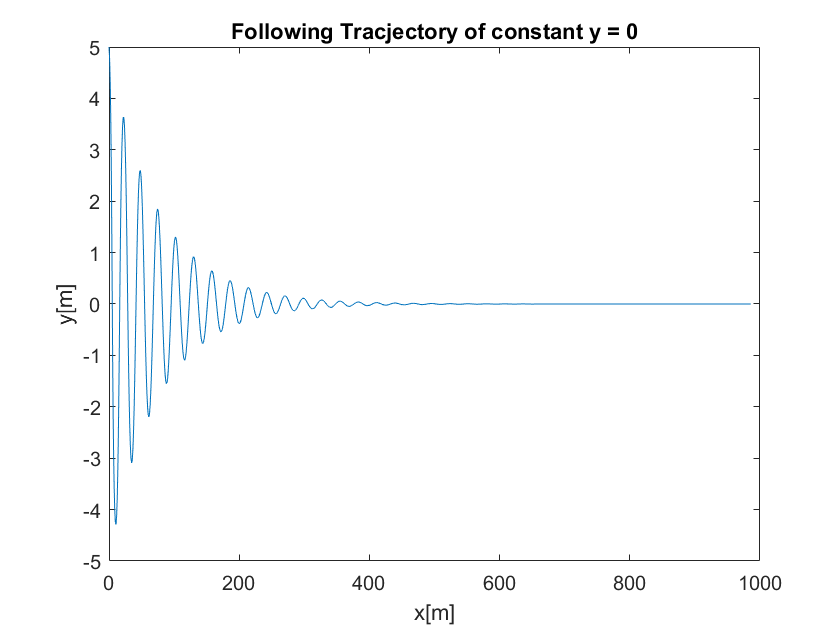

%Code of make the vehicle follow y=0 line.

%Using the model from ME542 Project without F_wind. For Linearization check
%HW9_ME542 solutions.
clear all; close all;
% fixed parameters
k_y = 0.05;
d=1.25;
l=2.5;
R =0;
m = 1500;
Jg = 2500;
m_0 = (Jg+m*d^2)/l^2;

% time
t0=0;
tend=100;

time=t0:0.1:tend;
y0 = [0;5;0;10];

[t,y] = ode45(@(t,y)odefunc(t,y,k_y,d,l,m,m_0,R),time,y0);


figure(1);
plot(y(:,1),y(:,2));
xlabel("x[m]");
ylabel("y[m]");
title("Following Tracjectory of constant y = 0")

function dydt = odefunc(t,y,k_y,d,l,m,m_0,R)

    y_star = 0;
    
    D = (y(2)-y_star);
    D_dot = 0;
    
    dydt(1) = y(4)*(cos(y(3)) + k_y*d*sin(y(3))*D/l);
    dydt(2) = y(4)*(sin(y(3)) - k_y*d*cos(y(3))*D/l);
    dydt(3) = y(4)*(-k_y*D);
    dydt(4) = (R-y(4)*m_0*(-k_y*D)*(-k_y*D_dot))/...
               (m + m_0*(k_y*y(2))^2);
    
    dydt = dydt';
end
